依赖[统一实验分析作图v17.2.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Naive hit miss 与 learned 的关系热图

预加载此脚本一次即可

DataSet=TransferLearning.FullCalcium;

统一实验分析作图v17.2.0已发布，<a href="https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases">立即更新</a>


QueryTable=UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'NaiveHitMiss');
Calcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(QueryTable,UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

Calcium=Calcium(any(Calcium.NTATS.Naive_light_water_hit,2),:);
Colors=GlobalOptimization.ColorAllocate(3,[1,1,1])

Colors =     1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000
    0.0000    1.0000    0.0000


NumMice=numel(unique(DataSet.Cells.Mouse(ismember(DataSet.Cells.CellUID,Calcium.CellUID))));

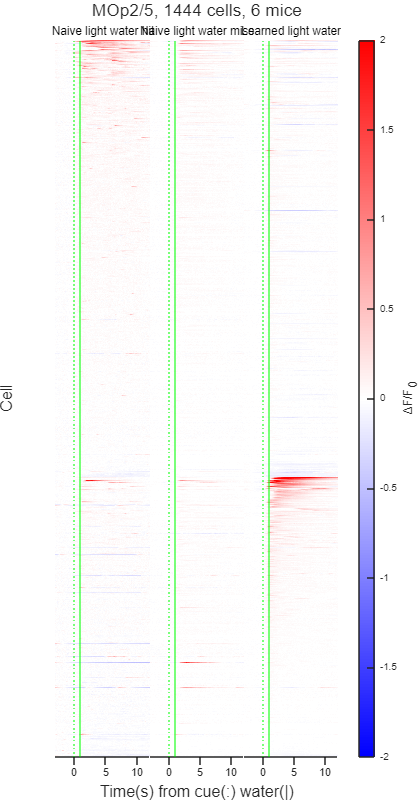

Layout=TransferLearning.BasicHeatmap(UniExp.HeatmapSort(Calcium,["Naive_light_water_hit","Learned_light_water"]).NTATS{:,:,["Naive_light_water_hit","Naive_light_water_miss","Learned_light_water"]},["Naive light water hit","Naive light water miss","Learned light water"],Colors([2,1,3],:),false,[-2,2]);
title(Layout,sprintf('MOp2/5, %u cells, %u mice',height(Calcium),NumMice));
MATLAB.Graphics.FigureAspectRatio(1,2,MATLAB.Flags.Amplify);
print(TransferLearning.ProjectPath('NaiveHitMiss.svg'),'-dsvg');